close all;

lls = 30e-6;
Cout = 1e-3;

Lm = 0.0001%10e-6;

Lm = 1.0000e-04

Llp =0.000001%30e-9;

Llp = 1.0000e-06

Cs = 0.000004%10e-6;

Cs = 4.0000e-06

Rload = 1%900;

Rload = 1

Re = 8/(pi^2)*Rload;

ws = logspace(10,10e+6);

fr1 = 1/(2*pi*sqrt(Cs*Llp)) % Resonant frequency at high load (Low Re)

fr1 = 7.9577e+04

fr2 = 1/(2*pi*sqrt(Cs*(Llp + Lm))) % Resonant frequency at low load (High Re)

fr2 = 7.9183e+03

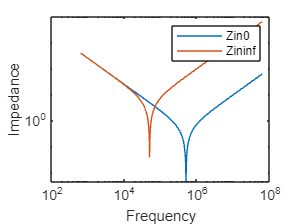


fs = logspace(2, 7, 1000);
ws = 2*pi*fs;

n = 1; %% turns ratio

Zin0 = abs(1./(Cs*1j*ws) + Llp*1j*ws);
Zininf = abs(1./(Cs*1j*ws) + Llp*1j*ws + Lm*1j*ws);

H_jw = abs(1./(1+(Re + Lm*1j*ws)./(Re*Lm.*1j*ws).*(1./(Cs*1j*ws) + Llp*1j*ws)));

figure('Name', 'Input impedence magnitude');
loglog(ws, Zin0)
hold on;
loglog(ws, Zininf)
ylabel('Impedance')
xlabel('Frequency')
legend('Zin0', 'Zininf');


M = n*H_jw/2;

fr1 = 1/(2*pi*sqrt(Cs*Llp)) % Resonant frequency at high load (Low Re)

fr1 = 7.9577e+04

fr2 = 1/(2*pi*sqrt(Cs*(Llp + Lm))) % Resonant frequency at low load (High Re)

fr2 = 7.9183e+03

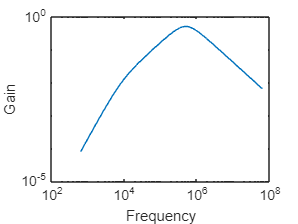

figure('Name', 'Gain of the converter vs freq');
loglog(ws, M)
ylabel('Gain')
xlabel('Frequency')


ws = 2*pi*127e+3;

H_jw = abs(1./(1+(Re + Lm*1j*ws)./(Re*Lm.*1j*ws).*(1./(Cs*1j*ws) + Llp*1j*ws)))

H_jw = 0.8544

Vin = 50;
V0 = n*H_jw/2*Vin

V0 = 21.3612